# 7 Численное моделирование. ode45

**Цель**: познакомится с решателем дифференциальных уравнений ode45

На прошлом занятии, мы познакомились с тем, как работает численное моделирование и в чём его суть. Мы составляли с вами системы уравнений для исследования некоторых физических система, потом строили их физическую и математическую модель. В итоге у нас получался алгоритм для расчёта математической модели. На это занятии мы применим уже разработанные алгоримты решения дифференциальных уравнений.

## 1 Решатель

Решателем называется алгоритм или функция, которая решает систему дифференциальных уравнений определенным методом. Разные дифференциальные уравнения имеют разные характеристики, которые будут разбираться в курсах вычислительной математики и дифференциальных уравнений. Мы же остановимся на нескольких методах.

Моделирование полёта аэростата может быть выполнено путем решения системы дифференциальных уравнений его движения численными методами, например, явным методом Рунге-Кутты.

В MATLAB существует функция ode45, в которой реализован метод Дормана-Принса 4-5 порядков точности (это подкласс методов Рунге-Кутты). Данный метод является достаточно универсальным, однако как и любой явный метод он имеет существенные ограничения при решении жёстких систем дифференциальных уравнений, что делает его практически не применимым к решению задач, содержащих разномасштабные по времени процессы.

Для задачи с аэростатом с учётом зависимости силы сопротивления воздуха от квадрата времени понадобилось использовать функцию ode89, которая лучше при интегрировании на длинных интервалах и при более жёстких требованиях к сходимости.

Описание метода выбора солвена приведено на странице помощи MATLAB, а также в статье https://www.mathworks.com/help/matlab/math/choose-an-ode-solver.html

## 2 Полёт аэростата (ode89)

% Удаление всех ранее созданных переменных
% При сдаче задачи в системе Grader данную строку писать не нужно
clear variables;

%  Численное решение системы дифференциальных уравнений с применением
%  метода Рунге-Кутты
u0 = [0; 0];
[t, u] = ode89(@aerostatModel, [0 4000], u0);

%  Извлечение переменных из решения, представляющего собой матрицу из
%  двух столбцов: y и v
y = u(:,1);
v = u(:,2);

#### Визуализация

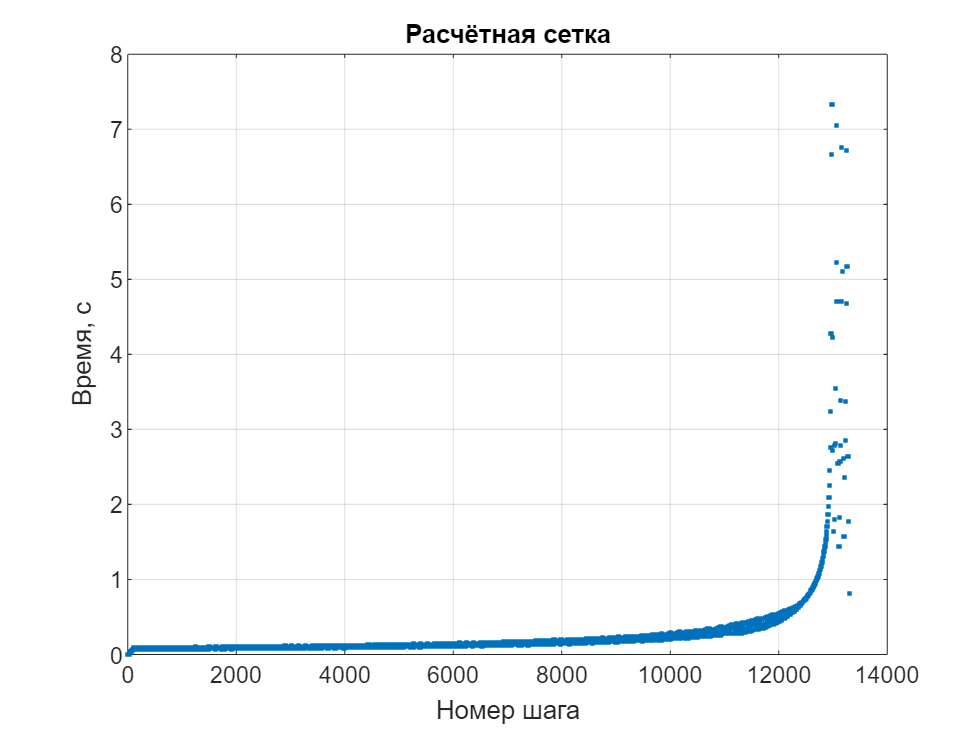

figure();
plot(abs(t(1:end-1) - t(2:end)), '.');
xlabel('Номер шага');
ylabel('Время, с');
title('Расчётная сетка');
grid on;

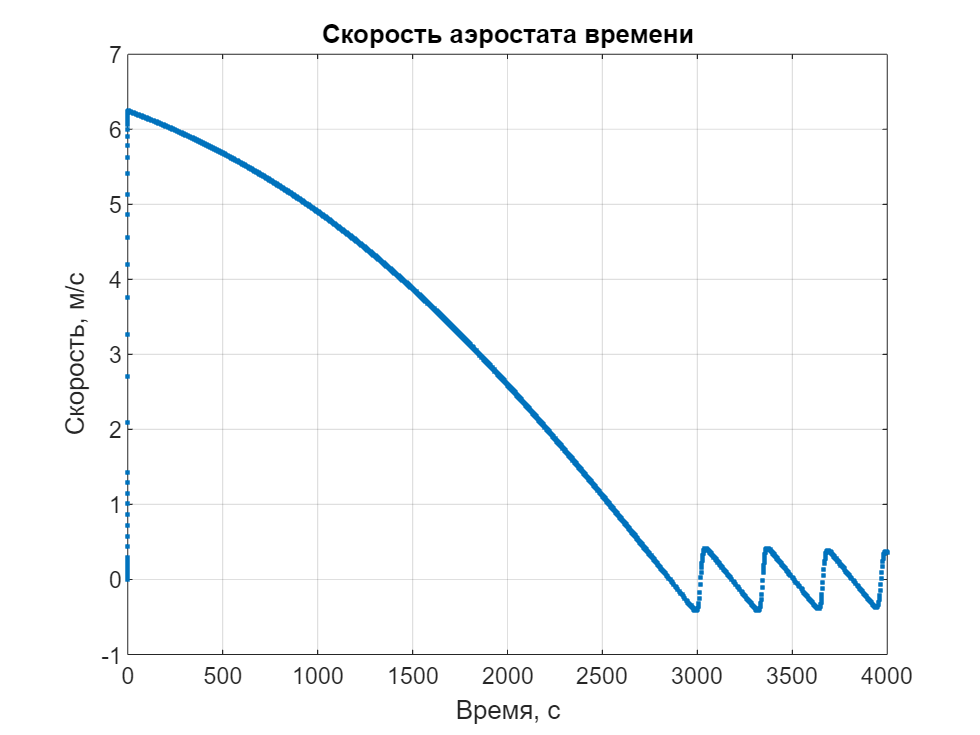

figure();
plot(t, v, '.');
xlabel('Время, с');
ylabel('Скорость, м/с');
title('Скорость аэростата времени');
grid on;

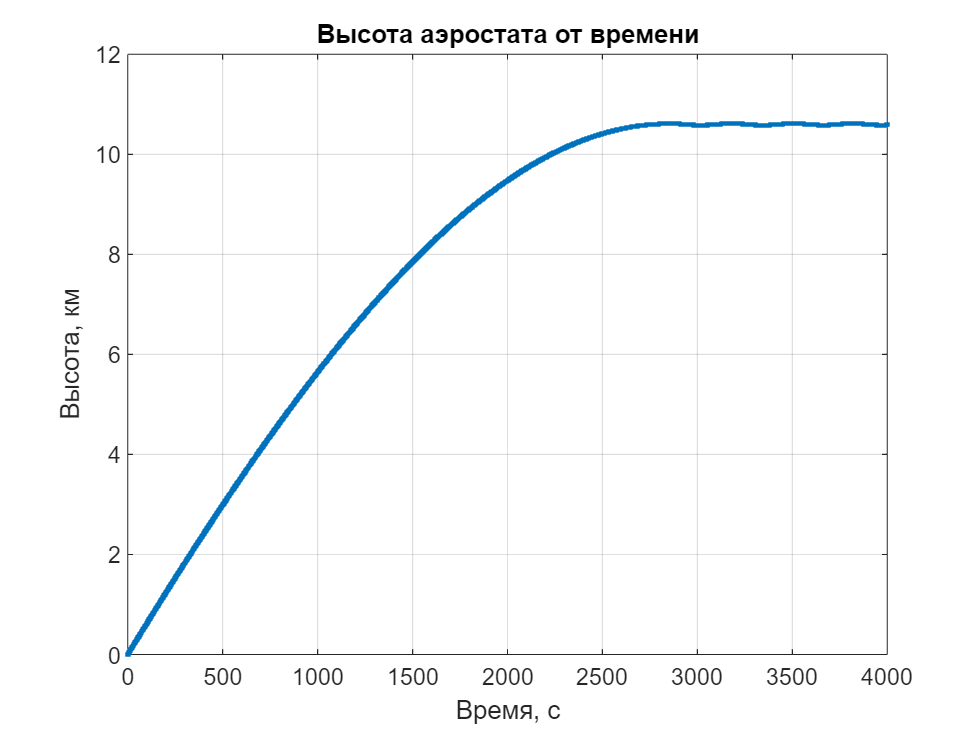


figure();
plot(t, y / 1e3, '.');
xlabel('Время, с');
ylabel('Высота, км');
title('Высота аэростата от времени');
grid on;

#### Функции

Численная модель зависимости плотности воздуха от высоты

% airDensity

Численная модель физической системы

%aerostatModel

## 3 Полёт ракеты

### 3.1 Физическое явление

В модели учитываются следующие физические явления:

- поступательное и вращательное движение твёрдого тела под действием сил и моментов

- гравитация

- зависимость плотности воздуха от высоты

- реактивная сила с отклоняемым вектором тяги

- сопротивление воздуха

- управление вращением за счёт решётчатых рулей

- подъёмная сила от набегающего потока воздуха

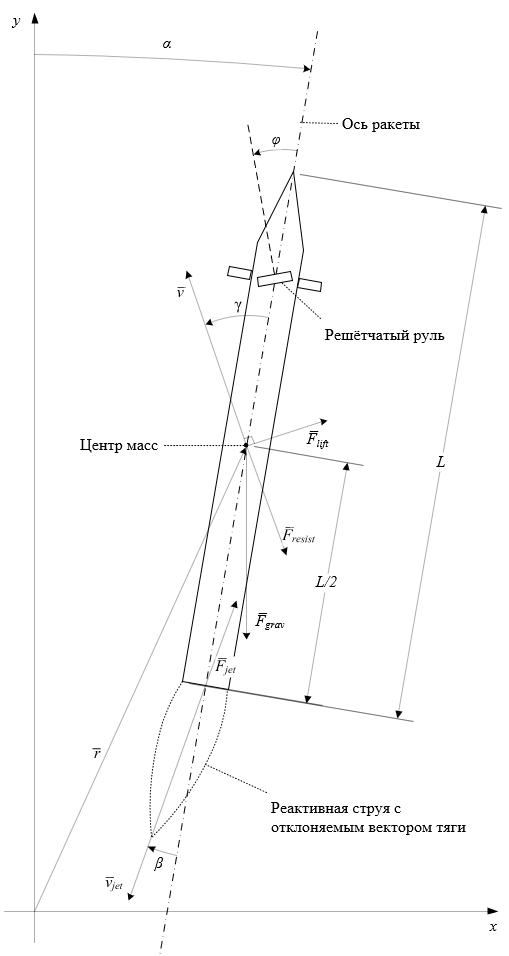

### 3.2 Физическая модель

**Общие положения**:

- двумерная модель (движение в плоскости)

- учитывается поступательное и вращательное движение твёрдого тела

- постоянное гравитационное поле** 9.8 м/с²**

- без учёта кривизны поверхности Земли (горизонтальное перемещение ракеты - не более 100 км, погрешность по высоте не более 1 км)

- плотность воздуха от высоты подчиняется барометрической формуле в положении, что атмосфера - идеальный газ с молярной массой **0.029 кг/моль**, с температурой ***T = *****300 К**, плотность воздуха на высоте 0 м составляет **1 кг/м³**

**Модель ракеты**:

- стержень с равномерно распределённой плотностью

- масса ракеты $m\left(t\right)$ зависит от времени и определяется расходом топлива $\mu \left(t\right)$

- масса пустой, не заправленной топливом ракеты, составляет **10 тонн**

- стартовая масса ракеты составляет** 20 тонн**

- длина ракеты $L$ составляет **70 м**

- cкорость истечения газов из сопла $\vec{v_{\mathrm{jet}} }$ = 20000 м/с

**Силы, действующие на ракету:**

- сила тяжести ${\vec{F} }_{\textrm{grav}}$ направлена против оси *y*

- реактивная сила${\vec{F} }_{\textrm{prop}}$ направлена вдоль линии реактивной струи с учётом отклонения на угол $\beta$

- сила сопротивления воздуха ${\vec{F} }_{\textrm{resist}}$ направлена против вектора скорости $\vec{v}$

- подъёмная сила ${\vec{F} }_{\textrm{lift}}$ направлена перпендикулярно вектору $\vec{v}$ и направлена в сторону ракеты, противоположную набегающему потоку воздуха

**Моменты сил, действующие на ракету (приведены проекции на ось *****z*****):**

- момент реактивной силы $M_{\textrm{prop}}$ зависит от угла отклонения вектора тяги $\beta$

- при вращении ракеты вокруг центра масс на ракету действует суммарный момент сил сопротивления $M_{\textrm{resist}}$

### 3.3 Математическая модель

Дифференциальное уравнение, описывающее изменение состояния ракеты от времени


$$\left\lbrace \begin{array}{ll}
\frac{\mathrm{d}}{\mathrm{d}t}m=\mu \left(t\right)\\
m\frac{d^2 }{\mathrm{d}t^2 }\vec{r} =\vec{F} \left(t\right)\\
I_z \;\frac{d^2 }{\mathrm{d}t^2 }\alpha =M_z \left(t\right)
\end{array}\right.$$


Для численного решения система дифференциальных уравнений должна быть приведена к форме системы дифференциальных уравнений первого порядка. Выполнив замену $\vec{v} =\frac{\mathrm{d}}{\mathrm{d}t}\vec{r}$ и $\omega =\frac{\mathrm{d}}{\mathrm{d}t}\alpha$ получим:


$$\left\lbrace \begin{array}{ll}
\frac{\mathrm{d}}{\mathrm{d}t}m=\mu \left(t\right)\\
\frac{\mathrm{d}}{\mathrm{d}t}\vec{r} =\vec{v} \\
\frac{\mathrm{d}}{\mathrm{d}t}\vec{v} =\frac{\vec{F} \left(t\right)}{m}\\
\frac{\mathrm{d}}{\mathrm{d}t}\alpha =\omega \\
\frac{\mathrm{d}}{\mathrm{d}t}\omega =\frac{M_z \left(t\right)}{I_z \;}
\end{array}\right.$$


получаем систему дифференциальных уравнений в форме, подходящей для численного решения:


$$\vec{\frac{\textrm{du}}{\textrm{dt}}} =f\left(t,\vec{u} \right)$$


Для численного решения необходимо также начальное условие для $t=0$:


$$\vec{u_0 } =\left\lbrack \begin{array}{c}
m_0 \\
0\\
0\\
0\\
0\\
0\\
0
\end{array}\right\rbrack$$
    

Матрица поворота вектора на угол $\theta$ по часовой стрелке в двумерном пространстве:


$$\left\lbrack \begin{array}{c}
x^{\prime } \\
y^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\cos \left(\theta \right) & \sin \left(\theta \right)\\
-\sin \left(\theta \right) & \cos \left(\theta \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack$$


### 3.4 Основные функции

Для выполнения задачи проще всего разбить ее на подзадачи. Мы требуем выполнять данное задание только при помощи функций, так как иначе помощь вам в проверке будет невозможна.

#### **3.4.1 Барометрическая формула (*****airDensity*****)**

Функция барометрической формулы. Данная функция должна на вход получать высоту `y`, а на выходе давать плотность `rho` на данной выосте.

**3.4.2 Функция управления (*****rocketControl*****)**

Данная функция получает на вход время `t `и текущую массу ракеты `m`, возвращает текущий массовый расход `massFlow` и угол поворота вектора тяги `beta`. Учесть, что масса топлива не должна быть меньше нуля.

**3.4.3 Сила тяжести (*****gracityForce)***

Функция расчёта сила тяжести. Поскольку наша задача двумерная, то данная функция должна возвращать вектор силы тяжести `F`. В лабораторной системе координат вектор на правлен противоположно оси y. На вход данная функция получает массу `m`

**3.4.4 Расчёт скорости истечения газов (*****jetStreamVelocity*****)**

Функция расчёта вектора скорости истекающих газов. На вход принимает угол наколнения ракеты `alpha` и угол отклонения оси сопла `beta`. Возвращает вектор скорости истечения газов `jetV`

**3.4.5 Реактивная сила (*****jetForce*****)**


$$F={\vec{u} }_{\textrm{gas}} \frac{\textrm{dm}}{\textrm{dt}}$$


Функция расчёта реактивной силы. Данная функция принимает на вход два аргумента: массовый расход топлива `massFlow`, вектор скорости истечения газов `jetV`. Возвращает вектор реактивной силы `F`

**3.4.6 Сила сопротивления воздуха (*****dragForce*****)**


$$F=C_F \frac{\rho \vec{\;v^2 } }{2}S$$


Функция расчёта силы сопротивления воздуха действующей на ракету. Данная функция принимает на вход вектор скорости ракеты `v`, плотность воздуха в текущей точке `rho`, а также угол гамма между вектором скорости и осью ракеты `gamma`.

**3.4.7 Момент инерции (*****interiaMoment*****)**

Функция расчёта момента инерции для стержня. На вход принимает массу `m` и длину ракеты `L`, возвращает момент инерции `I`.

**3.4.8 Момент реактивной силы (*****jetMomentum*****)**

Функция расчёта момента реактивной силы. Поскольку мы считаем моменты в проекции на ось z, то данная функция принимает на вход евклидову норму вектора реактивной силы (функция `norm`) `vnorm`, длину ракеты `L`, и угол отклонения оси сопла `beta`.

**3.4.9 Момент силы сопротивления воздуха при вращении (rotationDragMomentum)**


$$M_{\textrm{resist}} =k\;\omega \;\rho \;\frac{L}{2}$$


Поскольку наша ракеты в полёте может вращаться вокруг центра тяжести, то воздух будет оказывать силу сопротивления этому вращению. Данная функция на вход получает угловую скорость вращения ракеты `omega`, плотность воздуха в данной точке `rho `и длину ракеты `L`.

### **3.5 Численная модель ракеты (*****rocketModel*****)**

Основная функция для расчёта. На вход получает только время `t `и текущий вектор состояний `u`. На выход должна выдавать расчитанные производные для всех параметров состояний ракеты `dudt`. Порядок переменных в векторе состояний следующий:

- `m --     `масса ракеты (кг)

- `x --     `координата x радиус-вектора ракеты (м)

- `y --     `координата y радиус вектора ракеты (м)

- `vx --    `координата x вектора скорости ракеты (м/с)

- `vy --    `координата y вектора скорости ракеты (м/с)

- `alpha -- `угол наклонения ракеты в лабороторной системе отсчёта (рад)

- `omega -- `угловая скорость вращения ракеты (рад/с)

В функций должны выполняться следующие действия:

- Достать из вектора состояний `u` в переменные с понятными именами параметры ракеты.

- Описать необходимые в функции константы (ускорение свободного падения `g `и длины ракеты `L`)

- Расчитать угол `gamma` (угол между вектором скорости и углом наклонения ракеты)

- Рассчитать при помощи функции момент инерции `I` и записать в переменную

- Рассчитать при помощи фукнции текущую плотность `rho` и записать в переменную

- Рассчитать при помощи функции текущий массовый расход `massFlow` и угол отклонения вектора тяги **beta **и записать в переменные

- Рассчитать скорость истечения газов `jetV `и записать в переменную

- Рассчитать при помощи функций все силы и записать в отдельные переменные

- Найти сумму сил и записать в переменную

- Рассчитать при помощи функций все моменты и записать в переменные

- Найти сумму моментов и записать в переменную

- Сформировать вектор производных `dudt `для параметров ракеты в том же порядке, в котором они указаны в векторе состояний

### 3.6 Тестирование функций

После написания или во время написания функций обязательно проверить значения возвращаемые функциями данными тестами:

% Тесты для помощи студентам
% Проверки физических функций
test_airDensity             = airDensity([0 1 10 100]);
test_gravityForce           = gravityForce(1, 9.8);
test_jetForce               = jetForce(-20, [0; -2e4]);
test_dragForce              = dragForce([0; 1], 1, linspace(-pi, pi));
test_jetMomentum            = jetMomentum(1, 70 / 2, linspace(-0.01, 0.01));
test_dissipationMomentum    = rotationDragMomentum(linspace(-1, 1), 1, 1);


% Проверки численной модели в точке старта
test_rocketModel_1 = rocketModel(0, [20e3; 0; 0; 0; 0; 0; 0]);     % Проверка сил в покое
test_rocketModel_2 = rocketModel(0, [20e3; 0; 0; 0; 100; 0; 0]);   % Проверка сил при движении вверх
test_rocketModel_3 = rocketModel(0, [20e3; 0; 0; 0; 0; 0; 0.1]);   % Проверка моментов сил вращении

Рефернсные значения приведены в файле `test_data.mat`

### **3.7 Построение графиков**

Необходимо построить следующие графики:

- Координаты от времени: x(t), y(t)

- Скорость ракеты от времени: vx(t), vy(t), |v|(t)

- Тракеторию ракеты: y(x)

- Ориентацию ракеты: alpha(t)

- Угловую скорость ракеты: omega(t)

- Массу ракеты: m(t)